We will operate on qtdb database sampled at 250Hz

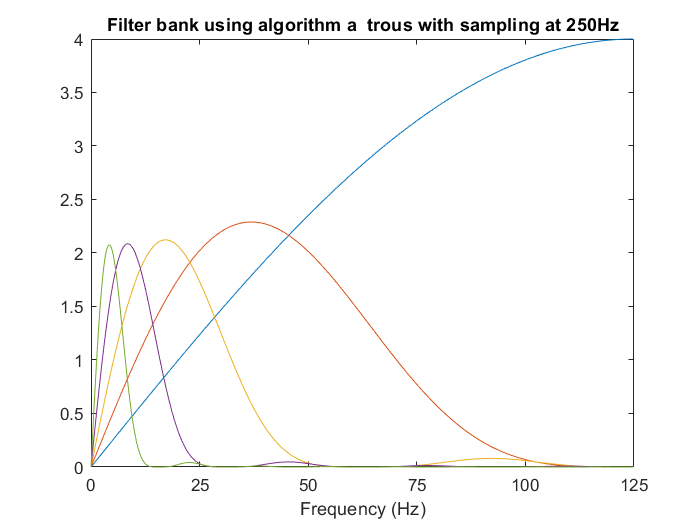

[record,a,b,c,d,e] = rdann('qtdb/sel230','pu0');
[sig, Fs, tm] = rdsamp('qtdb/sel230', 1);

fs = 250;
Gz = 2*[1 -1];
Hz = 1/8*[1 3 3 1];
level = 5;
G = {};
H = {};
G{1} = Gz;
H{1} = Hz;
for i = 1:level
    G{i+1} = upsample(Gz,2^i) ;
    H{i+1} = upsample(Hz,2^i) ; 
end

W{1} = G{1};
for i = 2:level
    temp = G{i};
    for j = 1:(i-1)
        temp = conv(temp , H{j});
    end
    W{i} = temp;
end
W{2}(end)=[];
for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]);
    q = q*125/pi;
    plot(q,abs(h));
    hold on
end
title 'Filter bank using algorithm a  trous with sampling at 250Hz'
xlabel 'Frequency (Hz)'
xlim([0,125])
xticks([0,25,50,75,100,125])

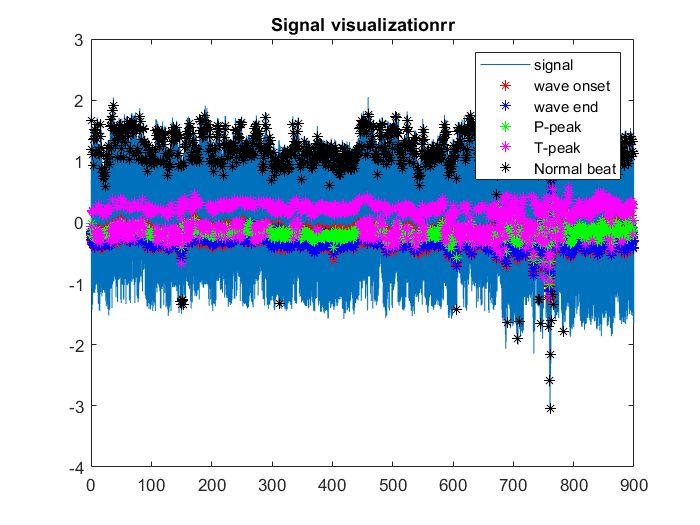

t=tm;
figure
plot(t,sig,t(record(find(a=='('))),sig(record(find(a=='('))),'r*');
hold on
plot(t(record(find(a==')'))),sig(record(find(a==')'))),'b*');
plot(t(record(find(a=='p'))),sig(record(find(a=='p'))),'g*');
plot(t(record(find(a=='t'))),sig(record(find(a=='t'))),'m*');
plot(t(record(find(a=='N'))),sig(record(find(a=='N'))),'k*');
legend('signal','wave onset','wave end','P-peak','T-peak','Normal beat')
title 'Signal visualization'rr

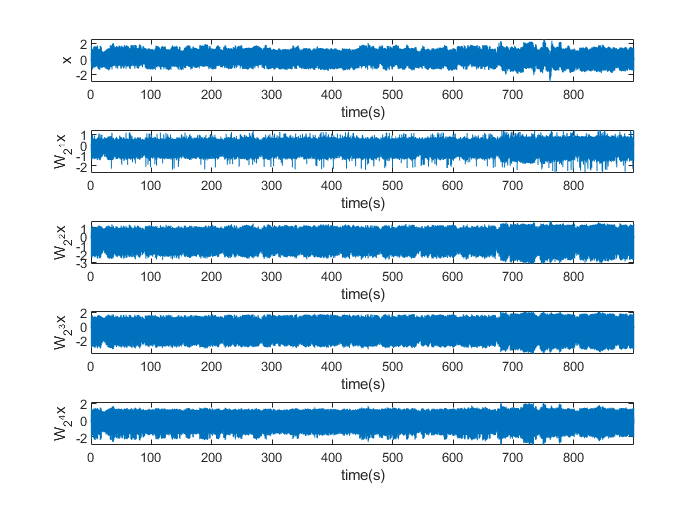

x=sig;
record_temp=record(find(a=='N'));
w1 = filter(W{1},[1],x);
w2 = filter(W{2},[1],x);
w3 = filter(W{3},[1],x);
w4 = filter(W{4},[1],x);

delay1=round(mean(grpdelay(W{1})));
delay2=round(mean(grpdelay(W{2})));
delay3=round(mean(grpdelay(W{3})));
delay4=round(mean(grpdelay(W{4})));
x=x(1:end-delay4);
t=t(1:end-delay4);

w1(1:delay1)=[];
w1=w1(1:end-delay4+delay1);
w2(1:delay2)=[];
w2=w2(1:end-delay4+delay2);
w3(1:delay3)=[];
w3=w3(1:end-delay4+delay3);
w4(1:delay4)=[];
figure()
title 'Filter outputs'
subplot(5,1,1)
plot(t,x)
axis tight
xlabel 'time(s)'
ylabel 'x'
subplot(5,1,2)
plot(t,w1)
xlabel 'time(s)'
axis tight
ylabel 'W_{2^1}x'
subplot(5,1,3)
plot(t,w2)
xlabel 'time(s)'
axis tight
ylabel 'W_{2^2}x'
subplot(5,1,4)
plot(t,w3)
axis tight
xlabel 'time(s)'
ylabel 'W_{2^3}x'
subplot(5,1,5)
plot(t,w4)
axis tight
xlabel 'time(s)'
ylabel 'W_{2^4}x'

Now we move to peak detection

length = 2^10;
n4k=[];
n3k=[];
n2k=[];
n1k=[];
for i = 1:size(w4,1)
    e_4_QRS=rms(w4(max(i-length,1):min(size(w4,1),i+length)));
    if(abs(w4(i))>0.5*e_4_QRS)
        n4k=[n4k;i];
        e_3_QRS=rms(w3(max(i-length,1):min(size(w3,1),i+length)));
        set_3=abs(w3(max(1,i-5):min(i+5,size(w3,1))));
        if(max(set_3)>e_3_QRS)
            [val,max_pos]=max(set_3);
            n3k=[n3k;max(1,i-5)+max_pos-1];
            e_2_QRS=rms(w2(max(i-length,1):min(size(w2,1),i+length)));
            set_2=abs(w2(max(1,i-7):min(i+7,size(w2,1))));
            if(max(set_2)>e_2_QRS)
                [val,max_pos]=max(set_2);
                n2k=[n2k;max(1,i-7)+max_pos-1];  
                e_1_QRS=rms(w1(max(i-length,1):min(size(w1,1),i+length)));
                set_1=abs(w1(max(1,i-10):min(i+10,size(w1,1))));
                if(max(set_1)>e_1_QRS)
                    [val,max_pos]=max(set_1);
                    n1k=[n1k;max(1,i-10)+max_pos-1];   
                else
                    n1k=[n1k;0];
                end
            else
                n2k=[n2k;0];
                n1k=[n1k;0];
            end
        else
            n3k=[n3k;0];
            n2k=[n2k;0];
            n1k=[n1k;0];
        end
        
    end
end

n3k=n3k.*(n1k~=0);
n3k(find(n3k==0))=[];
n2k=n2k.*(n1k~=0);
n2k(find(n2k==0))=[];figure
n1k(find(n1k==0))=[];
n1k=unique(n1k);

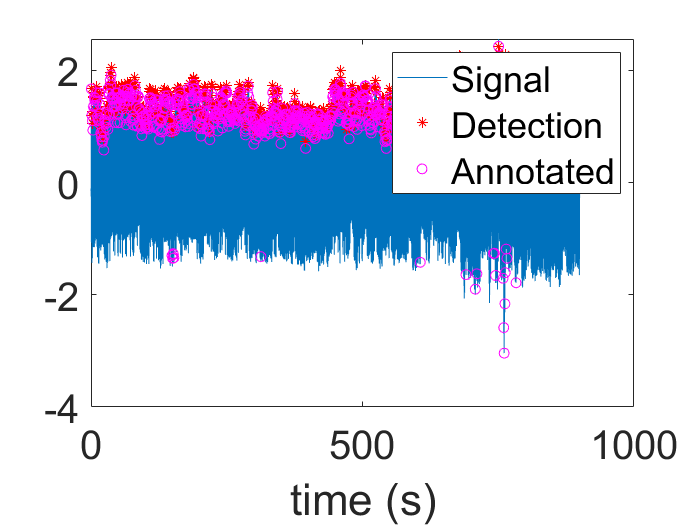

R=[];
for i = 1:size(n1k)-1
    if(w1(n1k(i))*w1(n1k(i+1))<0 & (n1k(i+1)-n1k(i))<20)
       piece = abs(w1(n1k(i):n1k(i+1)));
       [junk,pos] = min(piece);
       R=[R;n1k(i)-1+pos];
    end
end
count=1;
while count<size(R,1)
    if((R(count+1)-R(count))<30)
            R(count+1)=[];
            count=count+1;
    else
        count=count+1;
    end
end
figure
plot(t,x,t(R),x(R),'r*',t(record_temp),x(record_temp),'mo')
xlabel 'time (s)'
legend 'Signal' 'Detection' 'Annotated'
set(gca,'FontSize',24)

true_positive=0;
false_negative=0;
for i = 1:size(record_temp,1)
    if(min(abs(record_temp(i)-R))<5)
        true_positive=true_positive+1;
    else
        false_negative=false_negative+1;
    end
end
false_positive=0;
for i = 1:size(R,1)
    if(min(abs(R(i)-record_temp))>4)
        false_positive=false_positive+1;
    end
end
true_positive

true_positive = 1055

false_negative

false_negative = 21

false_positive

false_positive = 22

se=true_positive/(true_positive+false_negative)*100

se = 98.0483

p=true_positive/(true_positive+false_positive)*100

p = 97.9573

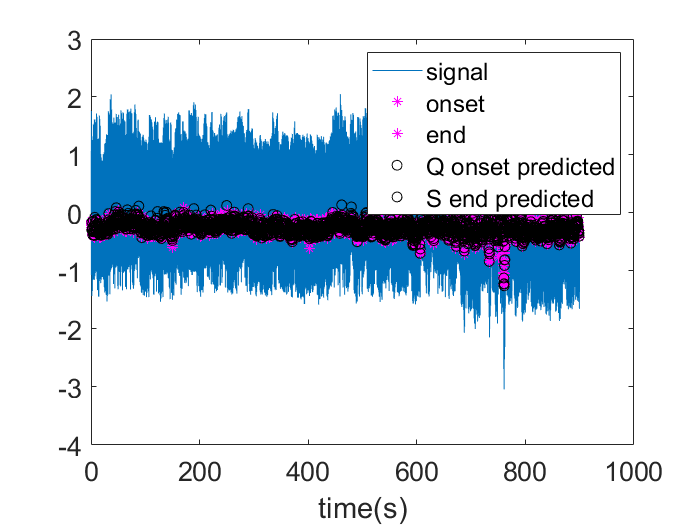

Repo=R;
Q_peak=[];
S_peak=[];
Q=[];
S=[];
maxima_post=[];
maxima_pre=[];
qq=size(Repo,1);
i=2;
while (i < qq)
    length=100;
    window_min = Repo(i)-length;
    window_max = Repo(i)+length;
    rr_wave_pre = abs(w2(window_min:Repo(i)));
    rr_wave_post = abs(w2(Repo(i):window_max));
    idx_pre = find((islocalmax(rr_wave_pre)>0) & (rr_wave_pre>0.06*max([rr_wave_pre;rr_wave_post])),2,'last');
    idx_post = find((islocalmax(rr_wave_post)>0) & (rr_wave_post>0.09*max([rr_wave_pre;rr_wave_post])),2,'first');
    if(size(idx_pre,1)<1)
        idx_pre=[window_min-2;window_min-1];
    elseif(size(idx_pre,1)==1)
        idx_pre=[idx_pre-1;idx_pre];        
    end
    if(size(idx_post,1)<1)
        idx_post=[1;2];
    elseif(size(idx_post,1)==1)
        idx_post=[idx_post;idx_post+1];        
    end
      maxima_post=[maxima_post;idx_post+Repo(i)-1];
    maxima_pre=[maxima_pre;idx_pre+Repo(i)-length-1];
    if(size(idx_pre,1)>1)
        if(w2(maxima_pre(end-1))>0)
            e_QRS_pre=0.05*abs(w2(maxima_pre(end-1)));
        else
            e_QRS_pre=0.07*abs(w2(maxima_pre(end-1)));          
        end
        QRS_on=abs(w2(window_min:maxima_pre(end-1)));
        QRS_on_1=QRS_on<e_QRS_pre;
        QRS_on_1=find(QRS_on_1>0,1,'last');
        QRS_on_2 = find(islocalmin(QRS_on)>0,1,'last');
        Q=[Q;max(QRS_on_2,QRS_on_1)-1+window_min];
    end
    if(size(idx_post,1)>1)
        if(w2(maxima_post(end))>0)
            e_QRS_post=abs(0.125*w2(maxima_post(end)));
        else
            e_QRS_post=abs(0.71*w2(maxima_post(end)));            
        end
        QRS_off = abs(w2(maxima_post(end):window_max));
        QRS_off_1 = QRS_off<e_QRS_post;
        QRS_off_2 = find(islocalmin(QRS_off)>0,1,'first');
        QRS_off_1 = find(QRS_off_1>0,1,'first'); 
        S=[S;min(QRS_off_1,QRS_off_2)-1+maxima_post(end)];
    end
    i=i+1;
end

close
figure
plot(t,x)
hold on
plot(t(record(a==')')),sig(record(a==')')),'m*');
plot(t(record(find(a=='('))),sig(record(find(a=='('))),'m*');
plot(t(Q),x(Q),'ko',t(S),x(S),'ko');

legend 'signal' 'onset' 'end' 'Q onset predicted' 'S end predicted'
xlabel 'time(s)'
set(gca,'FontSize',16)